## **In the name of God**

# Digital Signal Processing

# Computer Assignment #1

# **Alireza Javid**

# **810198375**

Part 1: Fourier Transform

M = [10,25,50,101]; 

**Rectangular Window: **$R_m \left\lbrack n\right\rbrack =u\;\left\lbrack n\right\rbrack -u\left\lbrack n-M\right\rbrack$

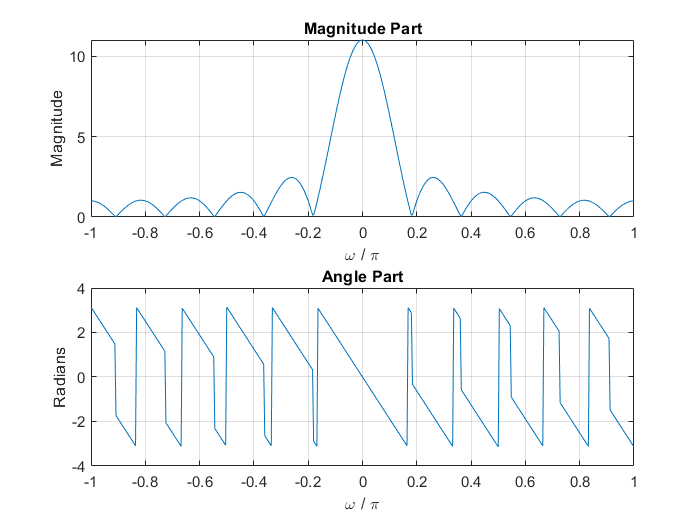

% M = 10
n = 0:M(1);
x = ones(1,length(n));
dtft(x);

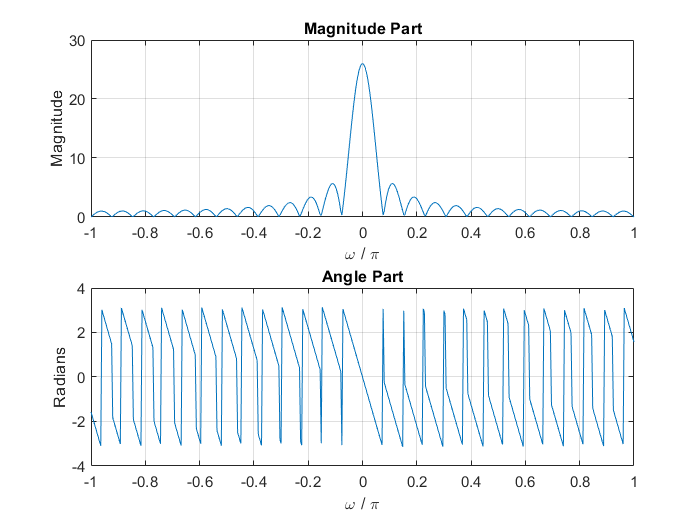

% M = 25
n = 0:M(2);
x = ones(1,length(n));
dtft(x);

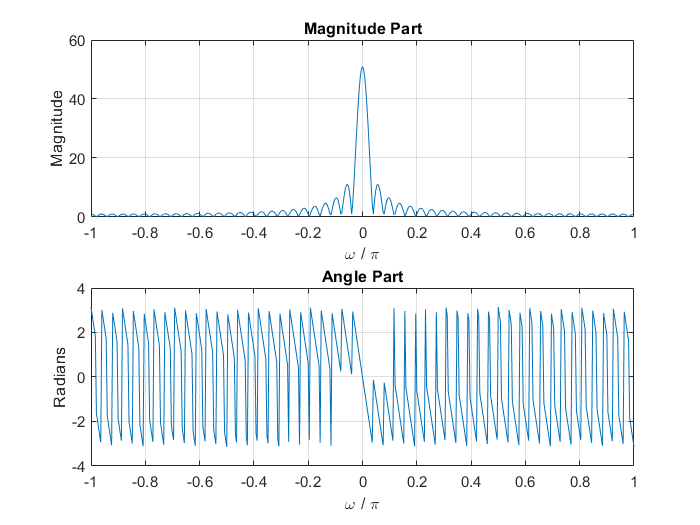

% M = 50
n = 0:M(3);
x = ones(1,length(n));
dtft(x);

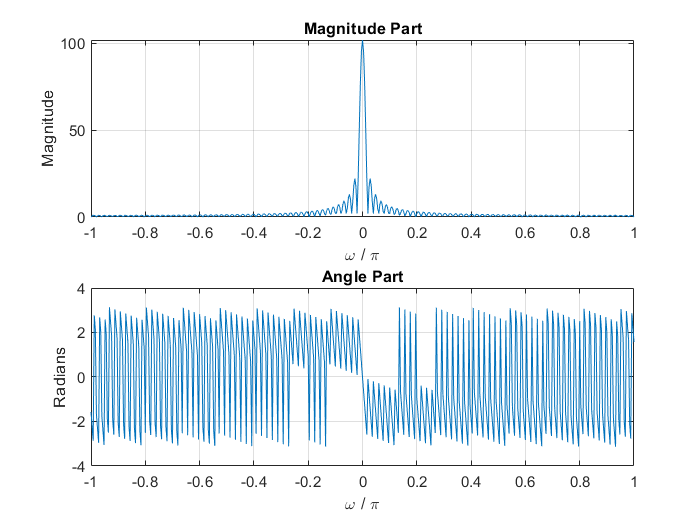

% M = 101
n = 0:M(4);
x = ones(1,length(n));
dtft(x);

**Hann Window:**  $C_m \left\lbrack n\right\rbrack =0\ldotp 5\;\left\lbrack 1-\cos \frac{2\;\pi \;n}{M-1}\right\rbrack \times R_m \left\lbrack n\right\rbrack$

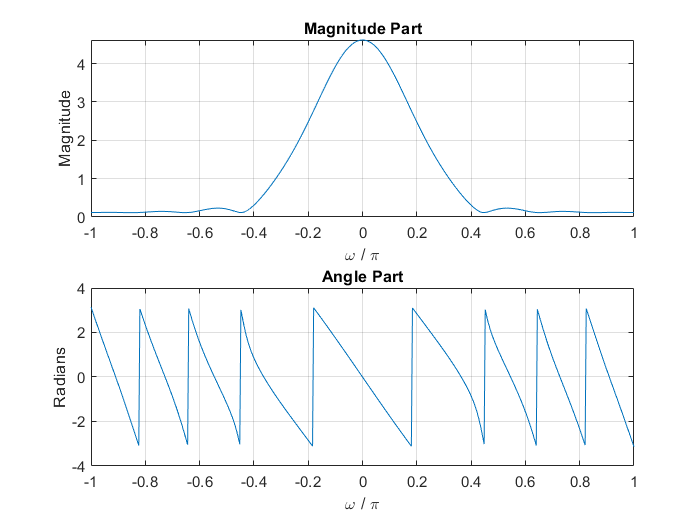

% M = 10
n = 0:M(1);
x = 0.5*(1-cos((2*pi*n)/(M(1)-1)));
dtft(x);

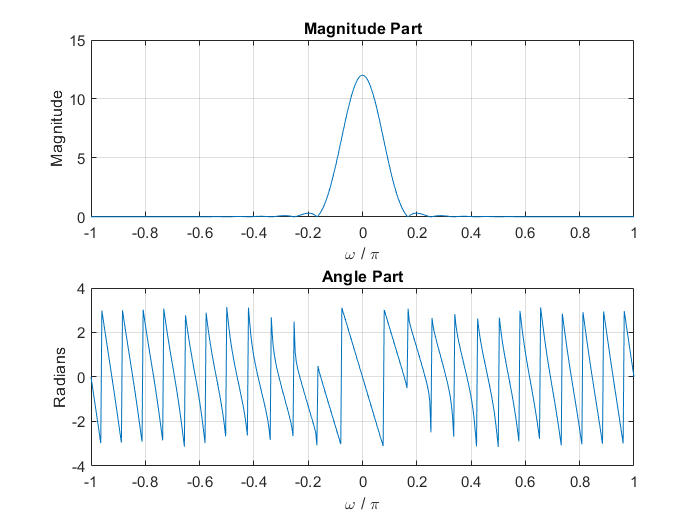

% M = 25
n = 0:M(2);
x = 0.5*(1-cos((2*pi*n)/(M(2)-1)) );
dtft(x);

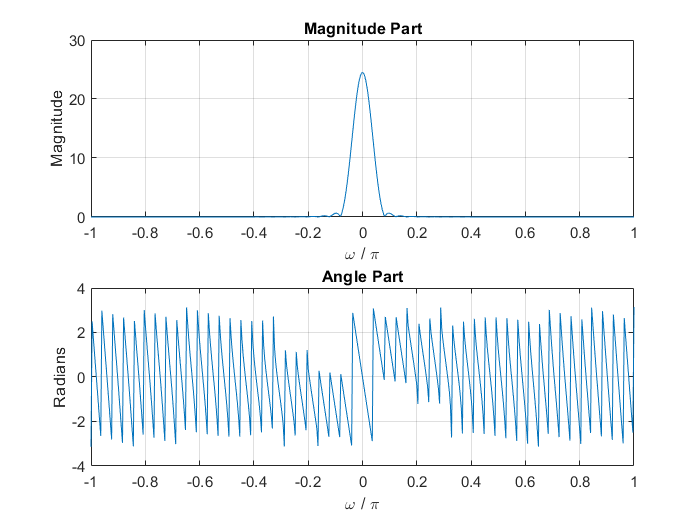

% M = 50
n = 0:M(3);
x = 0.5*(1-cos((2*pi*n)/(M(3)-1)) );
dtft(x);

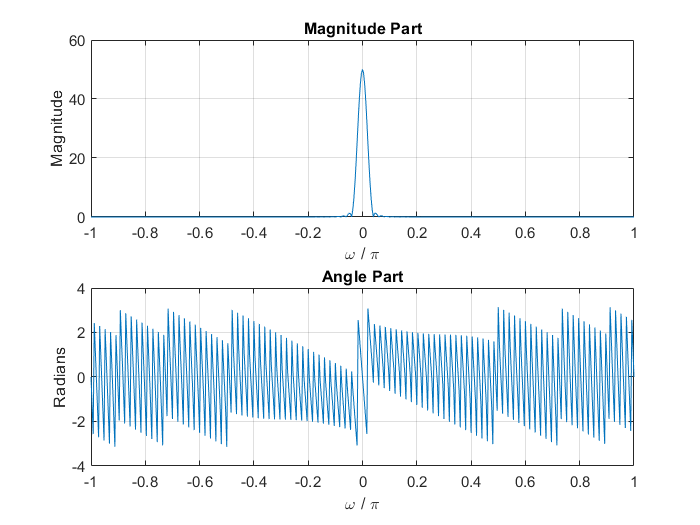

% M = 101
n = 0:M(4);
x = 0.5*(1-cos((2*pi*n)/(M(4)-1)) );
dtft(x);

**Triangular Window** : $T_M \left\lbrack n\right\rbrack =\left\lbrack 1-\frac{\left|M-1-2n\right|}{M-1}\right\rbrack \times R_M \left\lbrack n\right\rbrack$

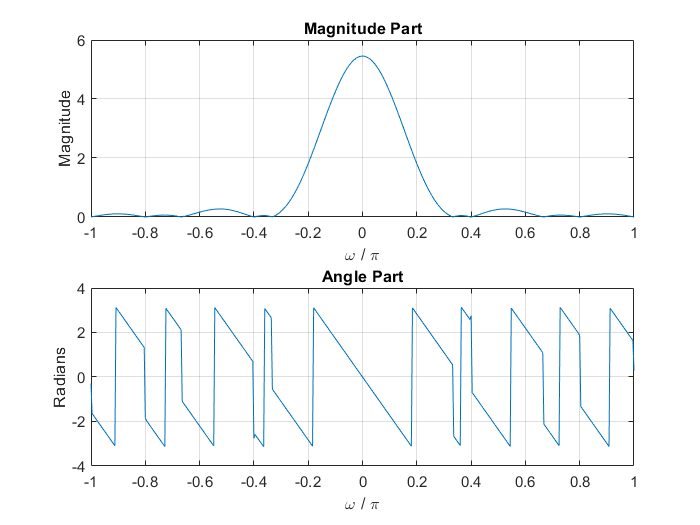

% M = 10
n = 0:M(1);
x = (1-(abs( M(1)-1-(2*n) )/(M(1)+1)));
dtft(x);

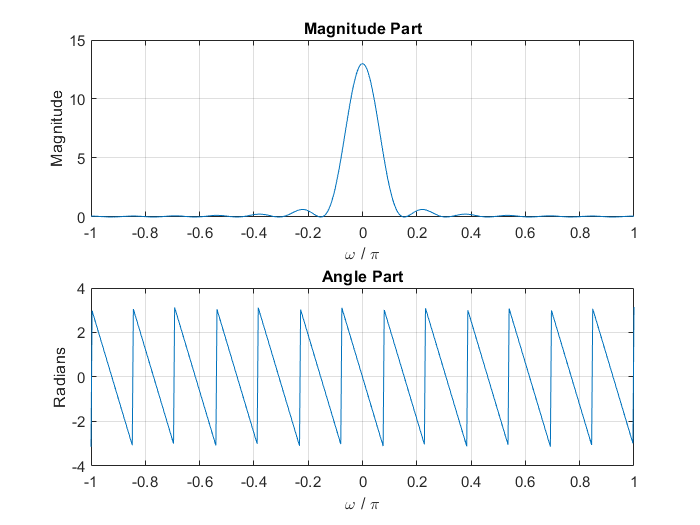

% M = 25
n = 0:M(2);
x = (1-(abs( M(2)-1-(2*n) )/(M(2)+1)));
dtft(x);

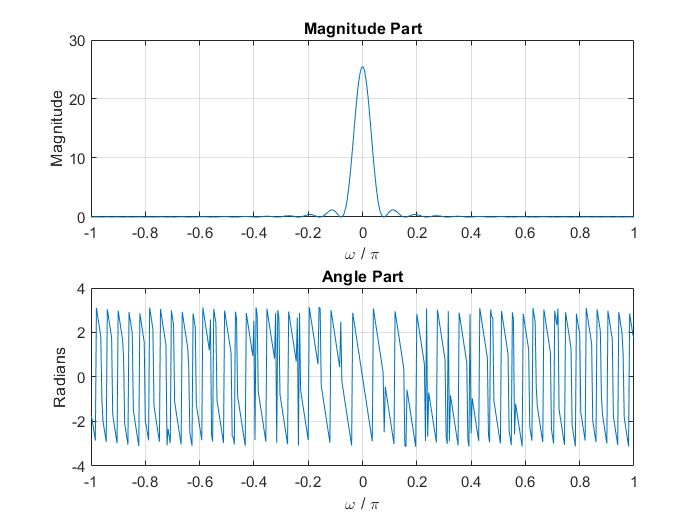

% M = 50
n = 0:M(3);
x = (1-(abs( M(3)-1-(2*n) )/(M(3)+1)));
dtft(x);

% M = 101
n = 0:M(4);
x = (1-(abs( M(4)-1-(2*n) )/(M(4)+1)));
dtft(x);

**Hamming Window:**  $H_M \left\lbrack n\right\rbrack =\left\lbrack 0\ldotp 54-0\ldotp 46\;\cos \left(\frac{2\;\pi \;n}{M-1}\right)\right\rbrack \times R_M \left\lbrack n\right\rbrack$

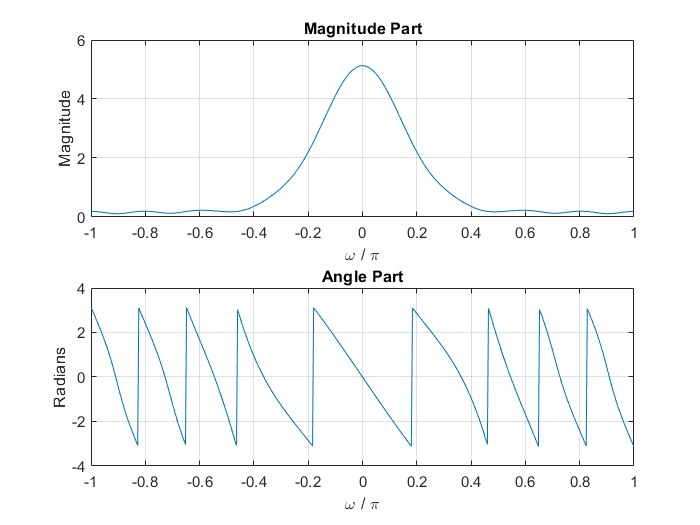


% M = 10
n = 0:M(1);
x = (0.54-0.46*cos((2*pi*n)/(M(1)-1)));
dtft(x);

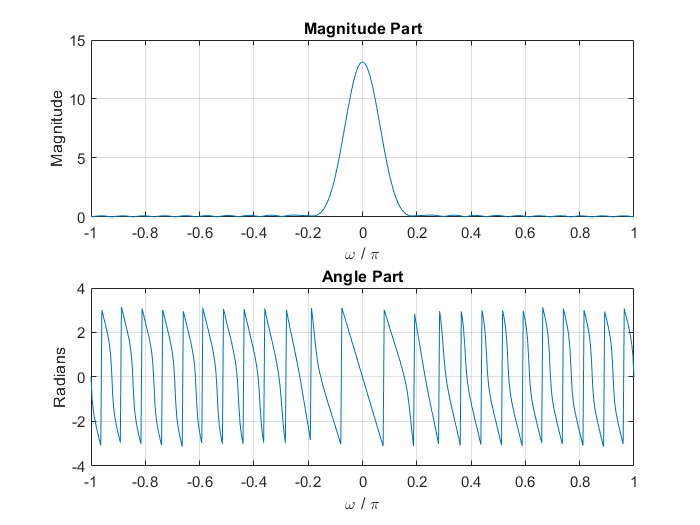

% M = 25
n = 0:M(2);
x = (0.54-0.46*cos((2*pi*n)/(M(2)-1)));
dtft(x);

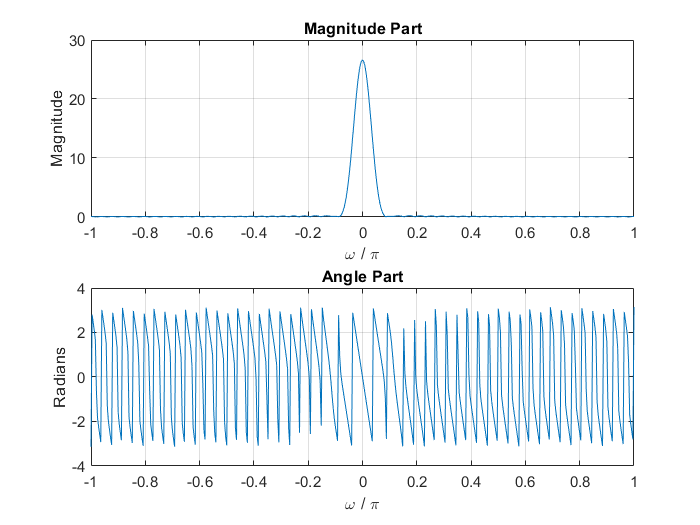

% M = 50
n = 0:M(3);
x = (0.54-0.46*cos((2*pi*n)/(M(3)-1)));
dtft(x);

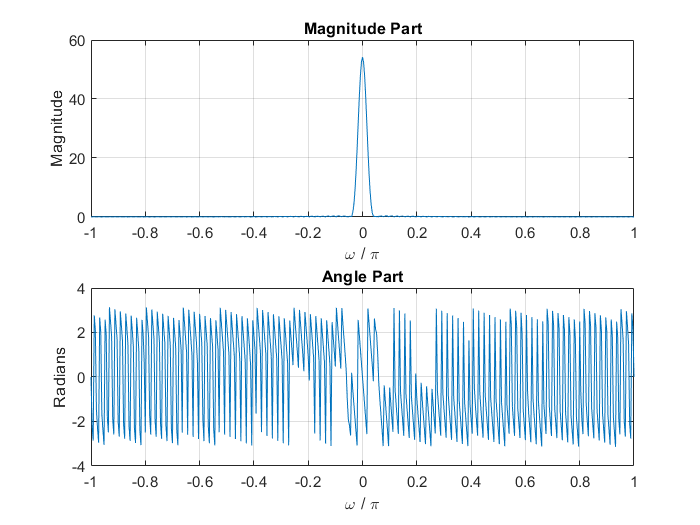

% M = 101
n = 0:M(4);
x = (0.54-0.46*cos((2*pi*n)/(M(4)-1)));
dtft(x);

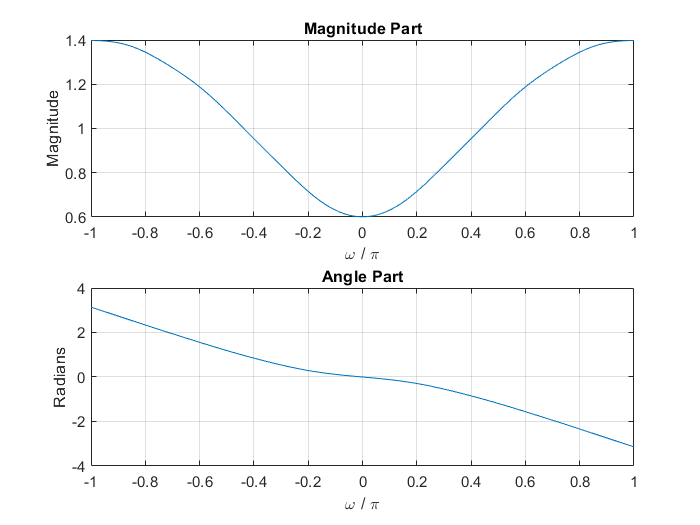

l = 1:6 ; a = 0.4.^l;
b = ones(1,1);
diff_resp(a,b);

part 2 : Interpolation


$$y[n]=\sum_{\ell=0}^3 x[n-2 \ell]-\sum_{m=1}^3(0.7)^m y[n-2 m]$$



$$x_1[n] = 1 + cos(\frac{\pi n + \pi}{2})$$


n = 0:200;
a = [1,0,0.7,0, 0.49,0, 0.343];
b = [1,0,1,0,1,0,1];
x1 = 1 + cos((pi*n + pi)/2);
y1 = filter(b,a,x1); 
Hs = stem(n,y1,'filled'); axis([-1 51 -3 5]);
title('Output response y(n) using the filter function');
ylabel('y(n)'); grid;


$$x_2[n]=\sum_{\ell=0}^5(\ell+1) \cos \left(\frac{\pi \ell n}{4}\right)$$


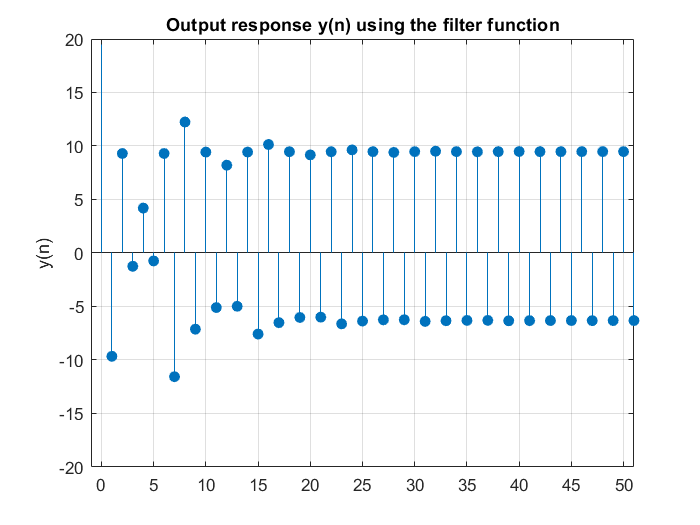

n = 0:200;
a = [1,0,0.7,0, 0.49,0, 0.343];
b = [1,0,1,0,1,0,1];
k = [0:5]; w = pi /4*k; A = (k+1);
term = w'*n;
x2 = A*cos(term);
y2 = filter(b,a,x2); 
Hs = stem(n,y2,'filled'); axis([-1 51 -20 20]);
title('Output response y(n) using the filter function');
ylabel('y(n)'); grid;

Compress Signal:


$$x\left\lbrack n\right\rbrack =\mathrm{sinc}\left(n\right)$$



$$M\in \left\lbrace 2,4\right\rbrace$$


fc = 8;
n = [-2:1/fc:2];
x = sinc(n);
M = [2,4];
x1 = compressor(x,M(1));
x2 = compressor(x,M(2));

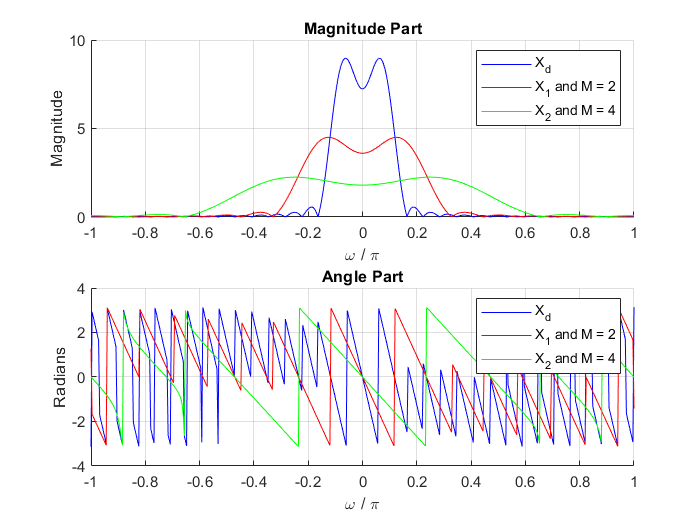

[Xd,w1] = dtft_no_plot(x);
[X1,w2] = dtft_no_plot(x1);
[X2,w3] =dtft_no_plot(x2);
magX = abs(Xd); angX = angle(Xd);
magX1 = abs(X1); angX1 = angle(X1);
magX2 = abs(X2); angX2 = angle(X2);
subplot(2,1,1); 
hold on;
p1 = plot(w1/pi,magX,'b'); 
p2 = plot(w2/pi,magX1,'r'); 
p3 = plot(w3/pi,magX2,'g'); grid;
hold off;
xlabel('\omega / \pi'); title('Magnitude Part'); ylabel('Magnitude')
h = [p1(1);p2;p3(1)];
legend(h,'X_d','X_1 and M = 2','X_2 and M = 4');
subplot(2,1,2); 
hold on;
p1 = plot(w1/pi,angX,'b'); 
p2 = plot(w2/pi,angX1,'r'); 
p3 = plot(w3/pi,angX2,'g'); grid;
xlabel('\omega / \pi'); title('Angle Part'); ylabel('Radians')
h = [p1(1);p2;p3(1)];
legend(h,'X_d','X_1 and M = 2','X_2 and M = 4');

Ecpand Signal:


$$x\left\lbrack n\right\rbrack =\textrm{sinc}\left(n\right)$$



$$L\in \left\lbrace 2,4\right\rbrace$$


fc = 8;
n = [-2:1/fc:2];
x = sinc(n);
L = [2,4];
xe1 = expander(x,L(1));
xe2 = expander(x,L(2));

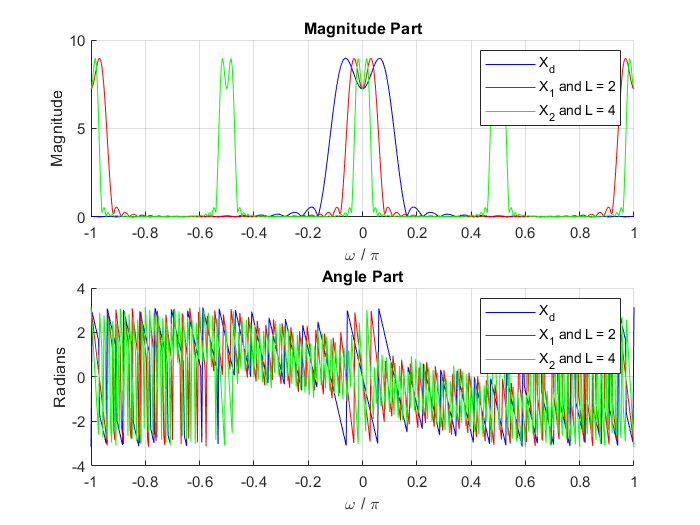

[Xd,w1] = dtft_no_plot(x);
[X1,w2] = dtft_no_plot(xe1);
[X2,w3] =dtft_no_plot(xe2);
magX = abs(Xd); angX = angle(Xd);
magX1 = abs(X1); angX1 = angle(X1);
magX2 = abs(X2); angX2 = angle(X2);
subplot(2,1,1); 
hold on;
p1 = plot(w1/pi,magX,'b'); 
p2 = plot(w2/pi,magX1,'r'); 
p3 = plot(w3/pi,magX2,'g'); grid;
hold off;
xlabel('\omega / \pi'); title('Magnitude Part'); ylabel('Magnitude')
h = [p1(1);p2;p3(1)];
legend(h,'X_d','X_1 and L = 2','X_2 and L = 4');
subplot(2,1,2); 
hold on;
p1 = plot(w1/pi,angX,'b'); 
p2 = plot(w2/pi,angX1,'r'); 
p3 = plot(w3/pi,angX2,'g'); grid;
xlabel('\omega / \pi'); title('Angle Part'); ylabel('Radians')
h = [p1(1);p2;p3(1)];
legend(h,'X_d','X_1 and L = 2','X_2 and L = 4');

Compress Signals:


$$x\left\lbrack n\right\rbrack =\mathrm{cos}\left(\frac{n\;\pi }{8}\right)$$



$$M\in \left\lbrace 2,4,8\right\rbrace$$


lim = 400;
n = 0:1:lim;
x = cos(n*pi/8);
M = [2,4,8];
x1 = compressor(x,M(1));
x2 = compressor(x,M(2));
x3 = compressor(x,M(3));

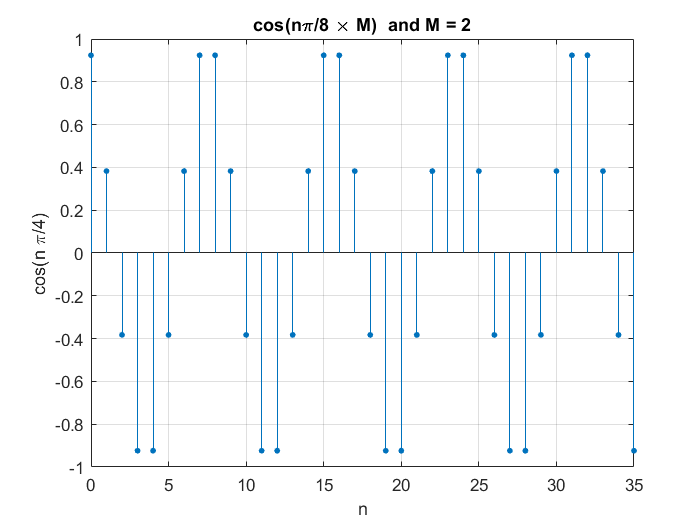

% M = 2
stem(0:35,x1(1:36),'filled','MarkerSize',3); grid;
xlabel('n'); title('cos(n\pi/8 \times M)  and M = 2'); 
ylabel('cos(n \pi/4)');

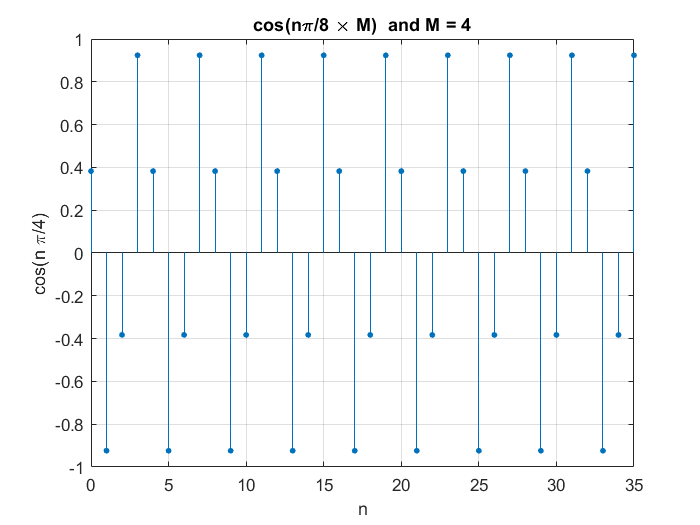

% M = 4
stem(0:35,x2(1:36),'filled','MarkerSize',3); grid;
xlabel('n'); title('cos(n\pi/8 \times M)  and M = 4'); 
ylabel('cos(n \pi/4)');

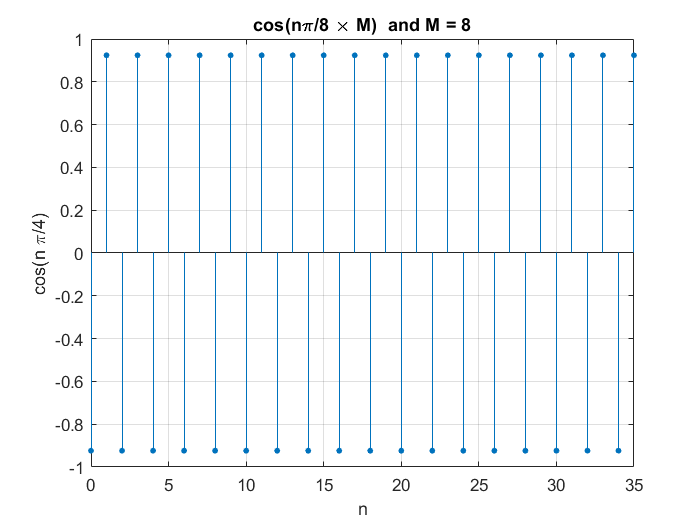

% M = 8
stem(0:35,x3(1:36),'filled','MarkerSize',3); grid;
xlabel('n'); title('cos(n\pi/8 \times M)  and M = 8'); 
ylabel('cos(n \pi/4)');

Using decimate function to compress

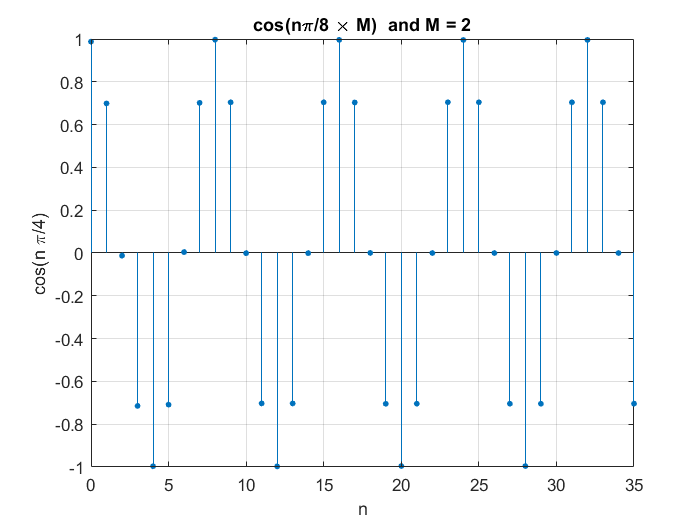

% M = 2
y = decimate(x,M(1));
stem(0:35,y(1:36),'filled','MarkerSize',3); grid;
xlabel('n'); title('cos(n\pi/8 \times M)  and M = 2'); 
ylabel('cos(n \pi/4)');

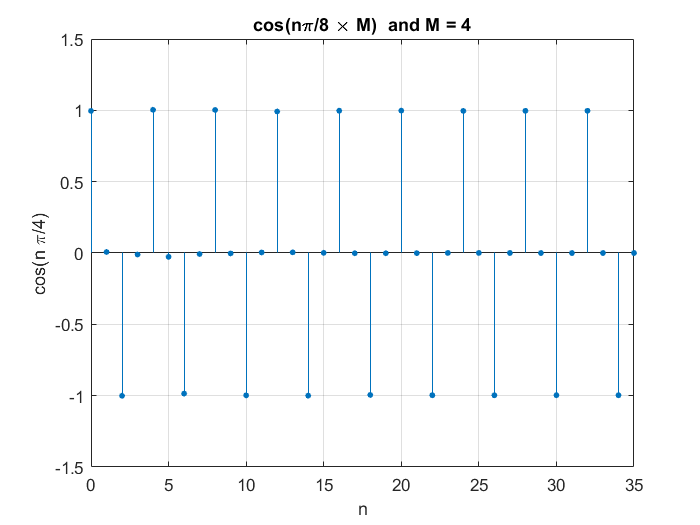

% M = 4
y = decimate(x,M(2));
stem(0:35,y(1:36),'filled','MarkerSize',3); grid;
xlabel('n'); title('cos(n\pi/8 \times M)  and M = 4'); 
ylabel('cos(n \pi/4)');

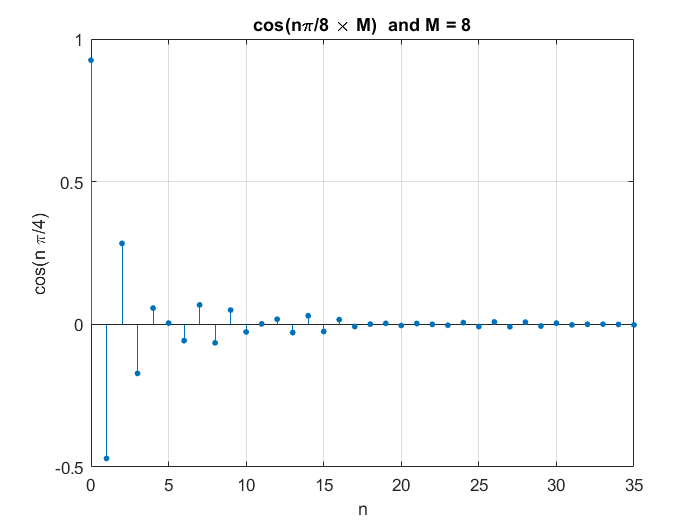

% M = 8
y = decimate(x,M(3));
stem(0:35,y(1:36),'filled','MarkerSize',3); grid;
xlabel('n'); title('cos(n\pi/8 \times M)  and M = 8'); 
ylabel('cos(n \pi/4)');

Reconstruction of an Analog Signal


$$x_a (t) = cos(40 \pi t + \theta) \:, \: 0 \ge t \ge 0.5$$



$$\theta \in \left\lbrace 0,\frac{\pi }{6},\frac{\pi }{2}\right\rbrace$$


$\Delta \;t=0\ldotp 001\;s\;$for analog signal                     $F_s =40\;\mathrm{Hz}$


$$L=\frac{1000}{40}=25$$


Fs = 40; Ts = 1/Fs; Dt = 0.001; t = 0:Dt:0.5; n = [0:50]; nTs = n*Ts;

- 
$$\theta =0$$


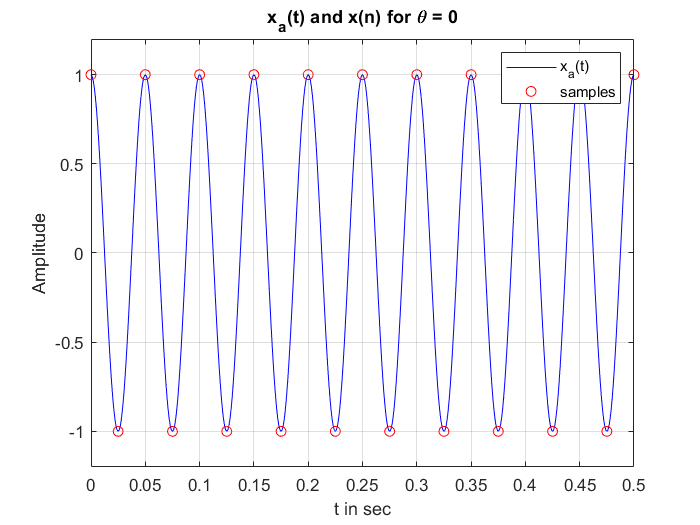

theta1 = 0; x_a1 = cos(40*pi*t+theta1); x1 = cos(40*pi*nTs+theta1);
plot(t,x_a1,'b'); 
axis([0 0.5 -1.2 1.2]); hold on;
plot(nTs,x1,'ro'); xlabel('t in sec');
title('x_a(t) and x(n) for \theta = 0');
ylabel('Amplitude'); grid;
legend('x_a(t)', 'samples')
hold off

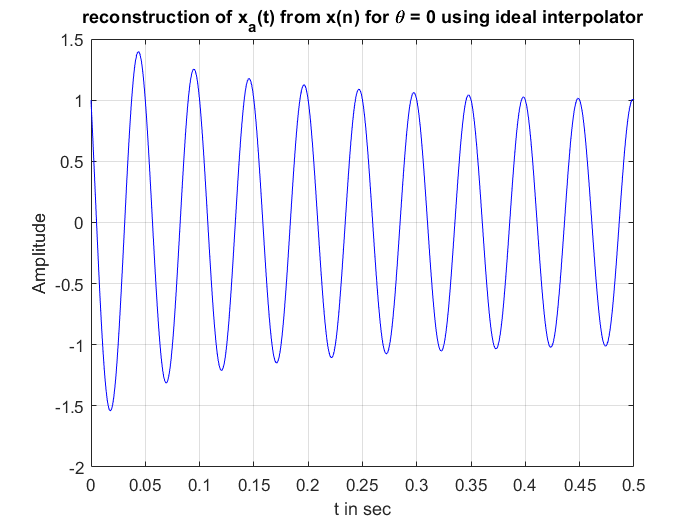

y1 = ideal_interpolation(x1,Ts,t);
plot(t,y1,'b'); xlabel('t in sec');
title('reconstruction of x_a(t) from x(n) for \theta = 0 using ideal interpolator');
ylabel('Amplitude'); grid;

err1 = immse(y1,x_a1)

err1 = 0.1681

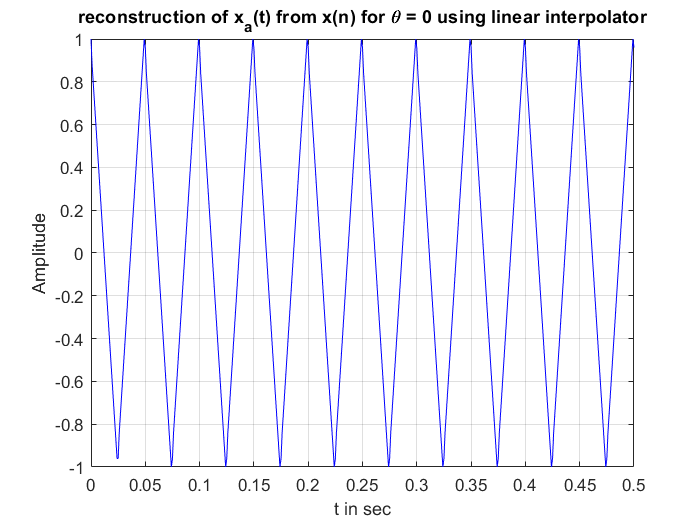

L = 1/(Dt * Fs);
y2 = linear_interpolation(x1,t,L);
plot(t,y2,'b'); xlabel('t in sec');
title('reconstruction of x_a(t) from x(n) for \theta = 0 using linear interpolator');
ylabel('Amplitude'); grid;

err2 = immse(y2,x_a1)

err2 = 0.0287

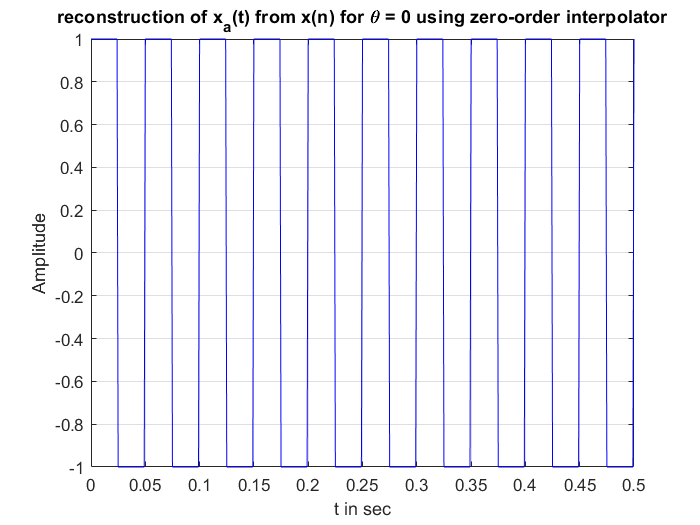

y3 = zero_order_interpolation(x1,t,L);
plot(t,y3,'b'); xlabel('t in sec');
title('reconstruction of x_a(t) from x(n) for \theta = 0 using zero-order interpolator');
ylabel('Amplitude'); grid;

err3 = immse(y3,x_a1)

err3 = 1.4172

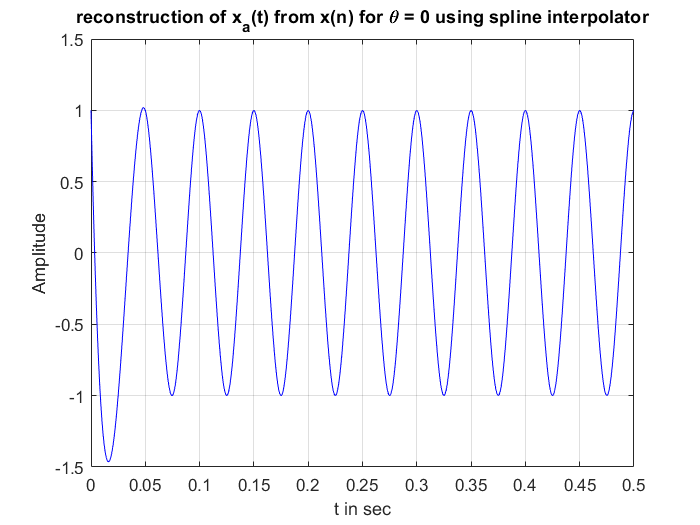

y4 = spline_interpolation(x1,t,Ts);
plot(t,y4,'b'); xlabel('t in sec');
title('reconstruction of x_a(t) from x(n) for \theta = 0 using spline interpolator');
ylabel('Amplitude'); grid;

err4 = immse(y4,x_a1)

err4 = 0.0566

disp('MSE for theta = 0');

MSE for theta = 0


fprintf('MSE for sinc interpolation: %f\n',err1);

MSE for sinc interpolation: 0.168096


fprintf('MSE for linear interpolation: %f\n',err2);

MSE for linear interpolation: 0.028683


fprintf('MSE for zero order interpolation: %f\n',err3);

MSE for zero order interpolation: 1.417166


fprintf('MSE for spline interpolation: %f\n',err4);

MSE for spline interpolation: 0.056610


    2. $\theta =\frac{\pi }{6}$

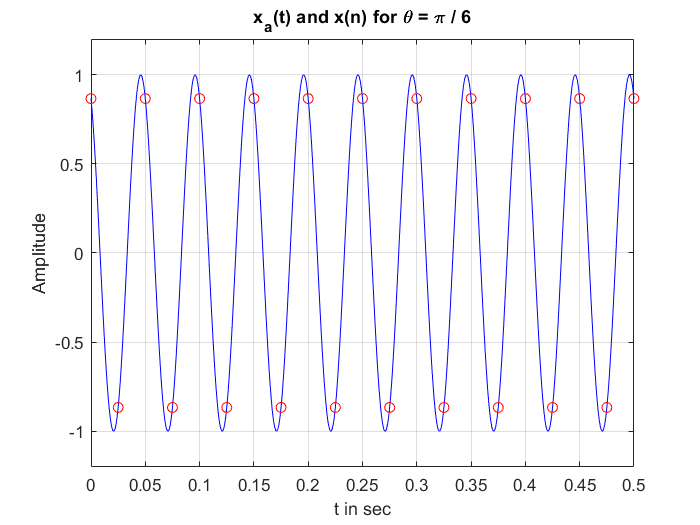

  theta1 = pi/6; x_a1 = cos(40*pi*t+theta1); x1 = cos(40*pi*nTs+theta1);
plot(t,x_a1,'b'); 
axis([0 0.5 -1.2 1.2]); hold on;
plot(nTs,x1,'ro'); xlabel('t in sec');
title('x_a(t) and x(n) for \theta = \pi / 6');
ylabel('Amplitude'); grid;
hold off

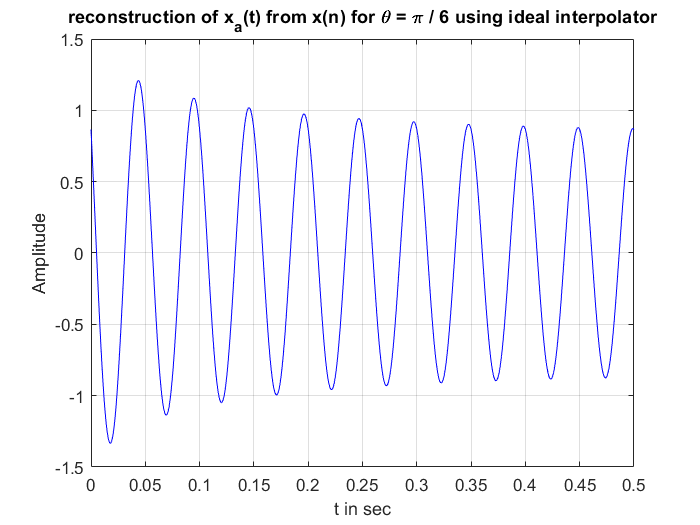

y1 = ideal_interpolation(x1,Ts,t);
plot(t,y1,'b'); xlabel('t in sec');
title('reconstruction of x_a(t) from x(n) for \theta = \pi / 6 using ideal interpolator');
ylabel('Amplitude'); grid;

err1 = immse(y1,x_a1)

err1 = 0.0345

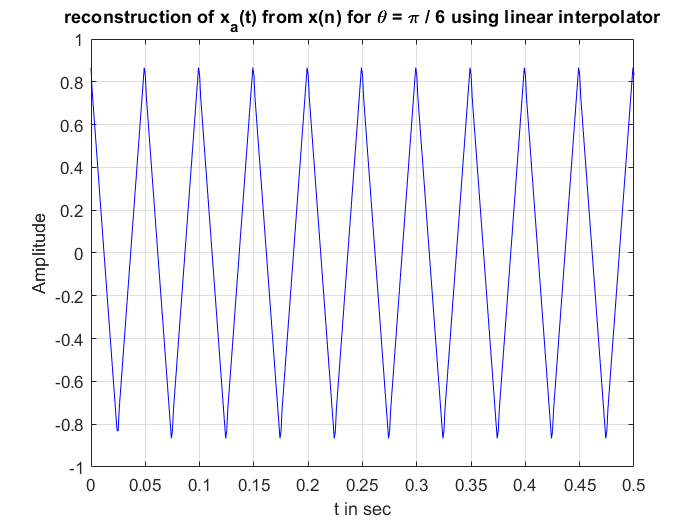

L = 1/(Dt * Fs);
y2 = linear_interpolation(x1,t,L);
plot(t,y2,'b'); xlabel('t in sec');
title('reconstruction of x_a(t) from x(n) for \theta = \pi / 6 using linear interpolator');
ylabel('Amplitude'); grid;

err2 = immse(y2,x_a1)

err2 = 0.1034

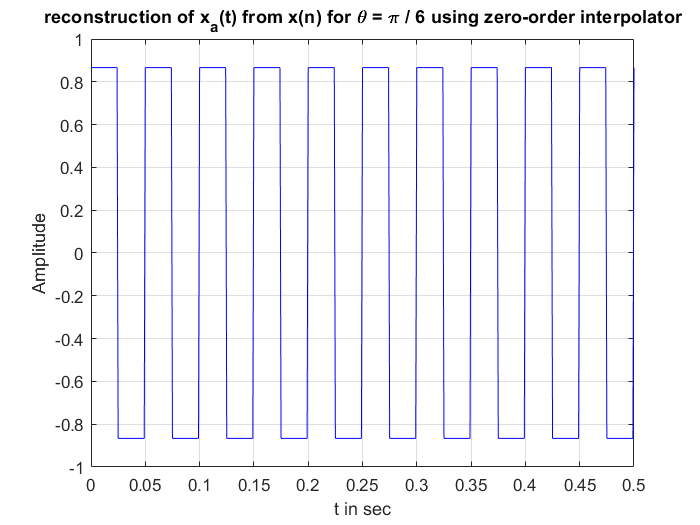

y3 = zero_order_interpolation(x1,t,L);
plot(t,y3,'b'); xlabel('t in sec');
title('reconstruction of x_a(t) from x(n) for \theta = \pi / 6 using zero-order interpolator');
ylabel('Amplitude'); grid;

err3 = immse(y3,x_a1)

err3 = 1.7371

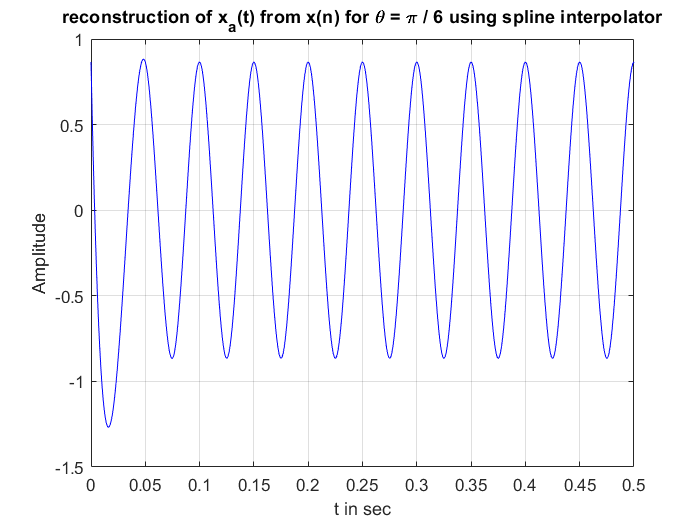

y4 = spline_interpolation(x1,t,Ts);
plot(t,y4,'b'); xlabel('t in sec');
title('reconstruction of x_a(t) from x(n) for \theta = \pi / 6 using spline interpolator');
ylabel('Amplitude'); grid;

err4 = immse(y4,x_a1)

err4 = 0.1256

disp('MSE for theta = pi / 6');

MSE for theta = pi / 6


fprintf('MSE for sinc interpolation: %f\n',err1);

MSE for sinc interpolation: 0.034535


fprintf('MSE for linear interpolation: %f\n',err2);

MSE for linear interpolation: 0.103402


fprintf('MSE for zero order interpolation: %f\n',err3);

MSE for zero order interpolation: 1.737129


fprintf('MSE for spline interpolation: %f\n',err4);

MSE for spline interpolation: 0.125596


    3. $\theta =\frac{\pi }{2}$

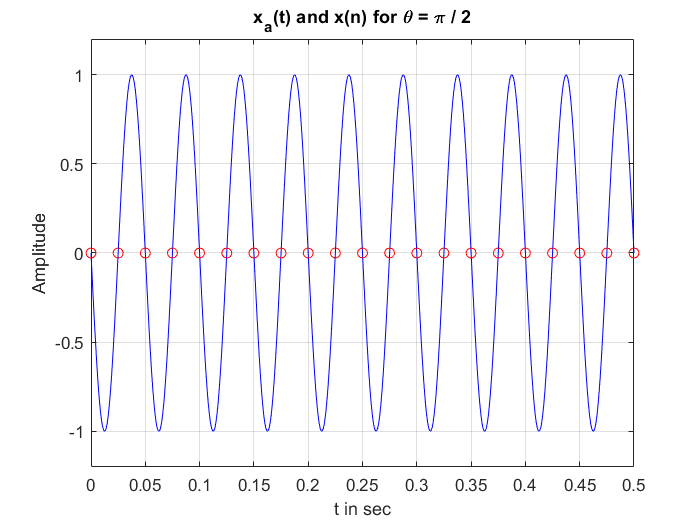

theta1 = pi/2; x_a1 = cos(40*pi*t+theta1); x1 = cos(40*pi*nTs+theta1);
plot(t,x_a1,'b'); 
axis([0 0.5 -1.2 1.2]); hold on;
plot(nTs,x1,'ro'); xlabel('t in sec');
title('x_a(t) and x(n) for \theta = \pi / 2');
ylabel('Amplitude'); grid;
hold off

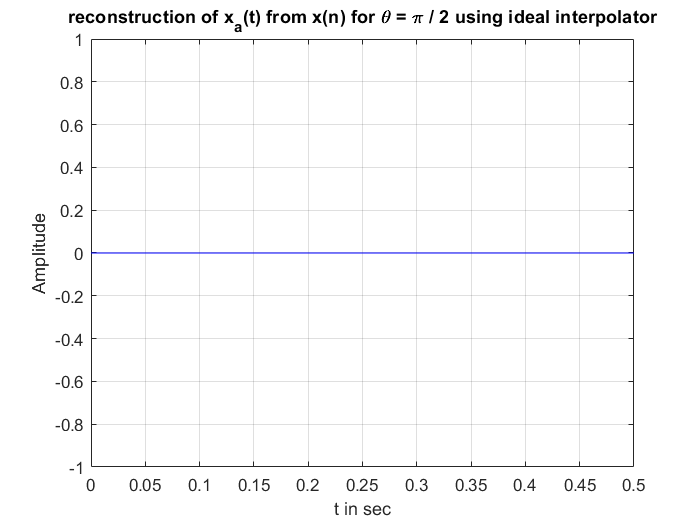

y1 = ideal_interpolation(x1,Ts,t);
plot(t,y1,'b'); xlabel('t in sec');
axis([0 0.5 -1 1]);
title('reconstruction of x_a(t) from x(n) for \theta = \pi / 2 using ideal interpolator');
ylabel('Amplitude'); grid;

err1 = immse(y1,x_a1)

err1 = 0.4990

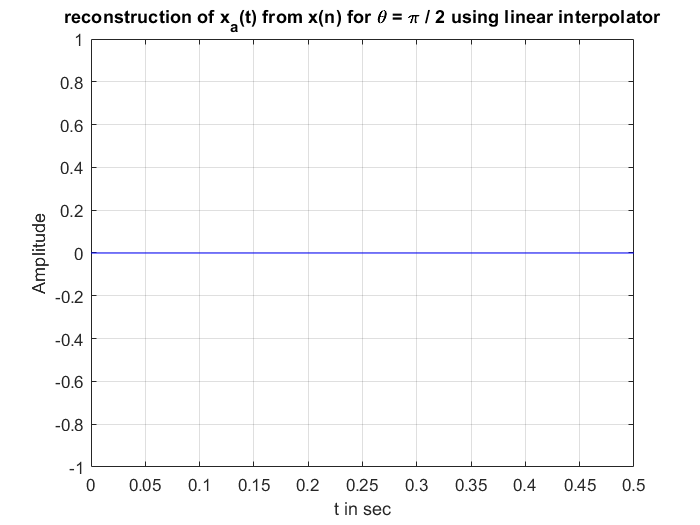

L = 1/(Dt * Fs);
y2 = linear_interpolation(x1,t,L);
plot(t,y2,'b'); xlabel('t in sec');
axis([0 0.5 -1 1]);
title('reconstruction of x_a(t) from x(n) for \theta = \pi / 2 using linear interpolator');
ylabel('Amplitude'); grid;

err2 = immse(y2,x_a1)

err2 = 0.4990

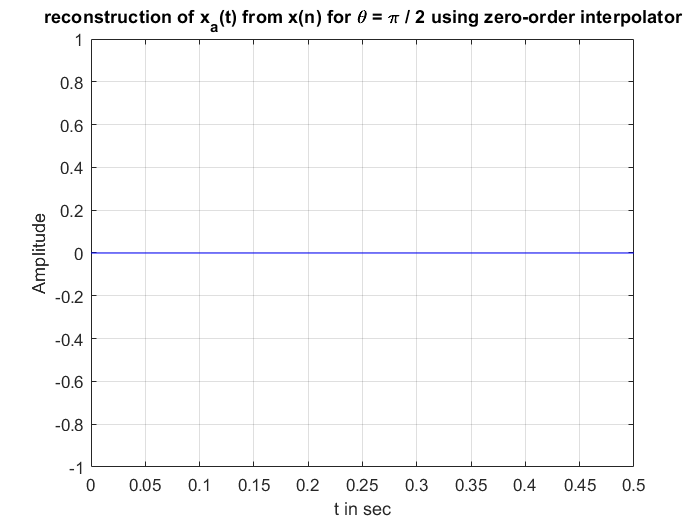

y3 = zero_order_interpolation(x1,t,L);
plot(t,y3,'b'); xlabel('t in sec');
axis([0 0.5 -1 1]);
title('reconstruction of x_a(t) from x(n) for \theta = \pi / 2 using zero-order interpolator');
ylabel('Amplitude'); grid;

err3 = immse(y3,x_a1)

err3 = 0.4990

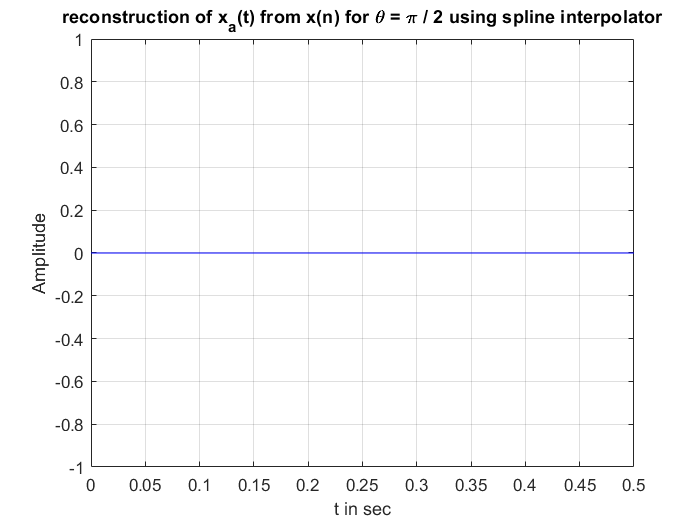

y4 = spline_interpolation(x1,t,Ts);
plot(t,y4,'b'); xlabel('t in sec');
axis([0 0.5 -1 1]);
title('reconstruction of x_a(t) from x(n) for \theta = \pi / 2 using spline interpolator');
ylabel('Amplitude'); grid;

err4 = immse(y4,x_a1)

err4 = 0.4990

disp('MSE for theta = pi / 2');

MSE for theta = pi / 2


fprintf('MSE for sinc interpolation: %f\n',err1);

MSE for sinc interpolation: 0.499002


fprintf('MSE for linear interpolation: %f\n',err2);

MSE for linear interpolation: 0.499002


fprintf('MSE for zero order interpolation: %f\n',err3);

MSE for zero order interpolation: 0.499002


fprintf('MSE for spline interpolation: %f\n',err4);

MSE for spline interpolation: 0.499002


part 3: z transform


$$y[n] - \frac{1}{6} y[n-1] - \frac{1}{3} y[n-2] = \frac{5}{6} - \frac{35}{36} x[n-1]
 - \frac{1}{2} x[n-2]$$


- Impulse Response

we use $	y[n] = \frac{5}{6} - \frac{35}{36} x[n-1] 	- \frac{1}{2} x[n-2] + \frac{1}{6} y[n-1] + \frac{1}{3} y[n-2] $ and $x\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack$

h = zeros(1,101);
for i = 1:101
    if i == 1
        h(i) = 5/6;
    elseif i== 2
        h(i) = 1/6*h(i-1) - 35/36;
    elseif i== 2
        h(i) = 1/6*h(i-1)+1/3*h(i-2)- 0.5;
    else
        h(i) = 1/6*h(i-1)+1/3*h(i-2);
    end
end

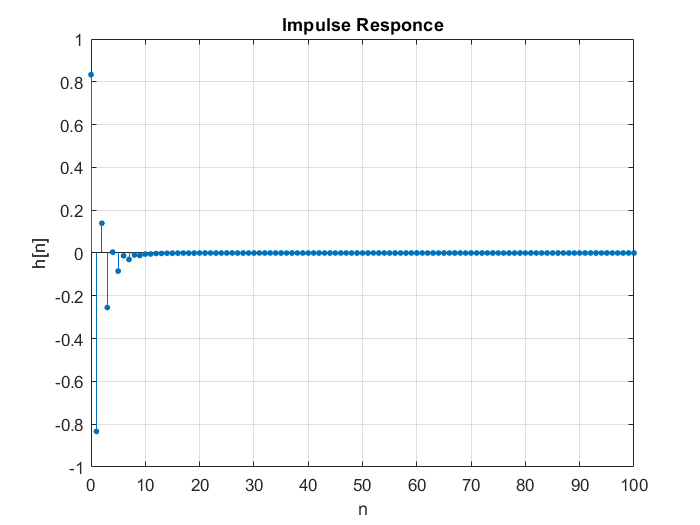

stem(0:100,h(1:101),'filled','MarkerSize',3); grid;
xlabel('n'); title('Impulse Responce'); 
ylabel('h[n]');

    2. System Output for $x\left\lbrack n\right\rbrack$


$$x[n] = (2 - \frac{4}{5} (\frac{1}{2})^n)$$


n = 0:100;
b = [5/6 -35/36 -1/2];
a = [1 -1/6 -1/3];
yi = [3 -1];
xi = [1 1];
x = 2 - 0.8 * 0.5.^n;
zi = filtic(b,a,yi,xi);


$$X_{+\;} \left(z\right)=\frac{2}{1-z^{-1} }-\frac{0\ldotp 8}{1-{\frac{1}{2}z}^{-1} }=\frac{1\ldotp 2-0\ldotp 2\;z^{-1} }{1-\frac{3}{2}z^{-1} +\frac{1}{2}z^{-2} }$$


bx = [1.2 -0.2];
ax = [1 -1.5 0.5];
ay = conv(a,ax);
by = conv(b,bx) + conv(zi,ax);
[r,p,c] = residuez(by,ay);

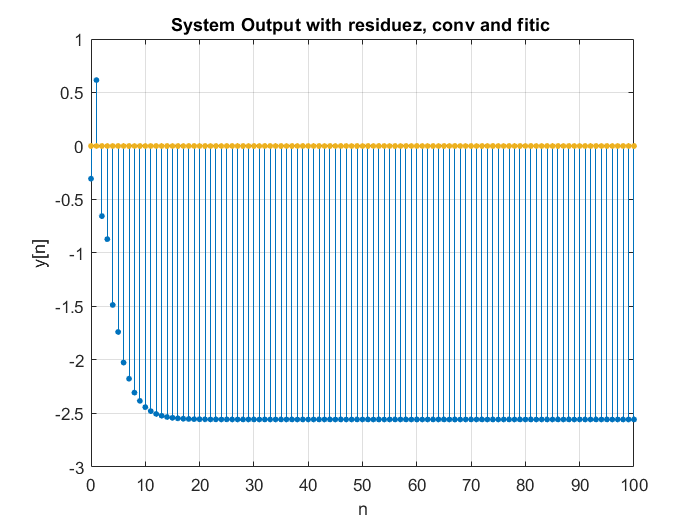

M = abs(p);
A = angle(p)/pi;
y1 = zeros(length(n));
% dtft inverse 
for i = n
    y1(i+1) = sum(r.*exp(-1i*pi*i*A).*(M.^i));
end
stem(n,real(y1),'filled','MarkerSize',3); grid;
title('System Output with residuez, conv and fitic ');
xlabel('n');
ylabel('y[n]');

    3. using filter function

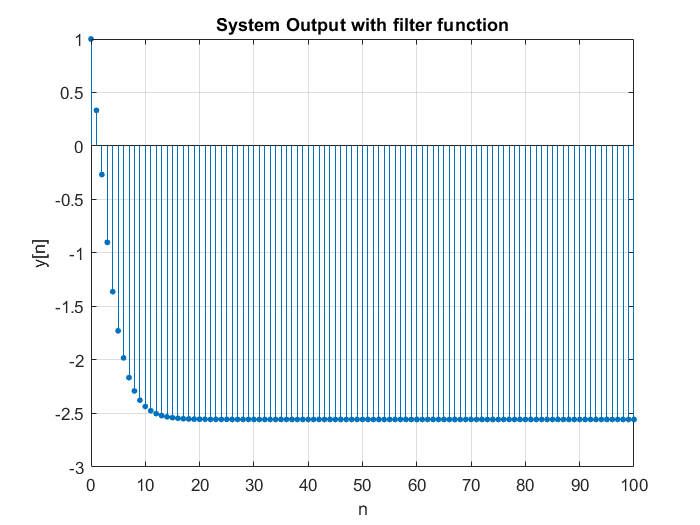

s = filter(b,a,x);
stem(0:100,s(1:101),'filled','MarkerSize',3); grid;
xlabel('n'); title('System Output with filter function'); 
ylabel('y[n]');

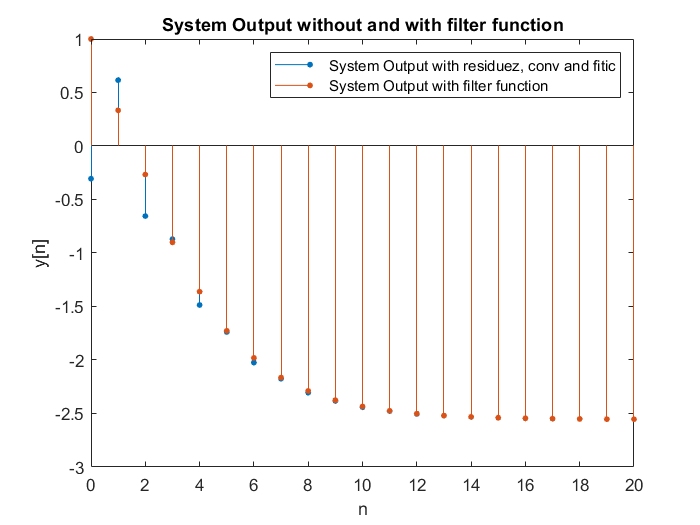

ry = real(y1);
stem(0:20,ry(1:21),'filled','MarkerSize',3); grid; 
hold on;
stem(0:20,s(1:21),'filled','MarkerSize',3); grid;
xlabel('n'); title('System Output without and with filter function'); 
ylabel('y[n]');
legend('System Output with residuez, conv and fitic', 'System Output with filter function')

    4. determain transient and steady-state response:

A'

ans =      0     0     1     0


M'

ans =     1.0000    0.6667    0.5000    0.5000


r'

ans =    -2.5556    6.8825   -0.8992   -3.7333


the complete response is:


$$y\left\lbrack n\right\rbrack =-2\ldotp 5556\;u\left\lbrack n\right\rbrack +6\ldotp 8825\;{\left(\frac{2}{3}\right)}^n u\left\lbrack n\right\rbrack -0\ldotp 8992\;{\left(-\frac{1}{2}\right)}^n u\left\lbrack n\right\rbrack -3\ldotp 7333{\left(\frac{1}{2}\right)}^n u\left\lbrack n\right\rbrack$$


So the steady-state response is:

 
$$y\left\lbrack n\right\rbrack =-2\ldotp 5556\;u\left\lbrack n\right\rbrack$$


And the transient response is:


$$y\left\lbrack n\right\rbrack \;=\;6\ldotp 8825\;{\left(\frac{2}{3}\right)}^n u\left\lbrack n\right\rbrack -0\ldotp 8992\;{\left(-\frac{1}{2}\right)}^n u\left\lbrack n\right\rbrack -3\ldotp 7333{\left(\frac{1}{2}\right)}^n u\left\lbrack n\right\rbrack$$


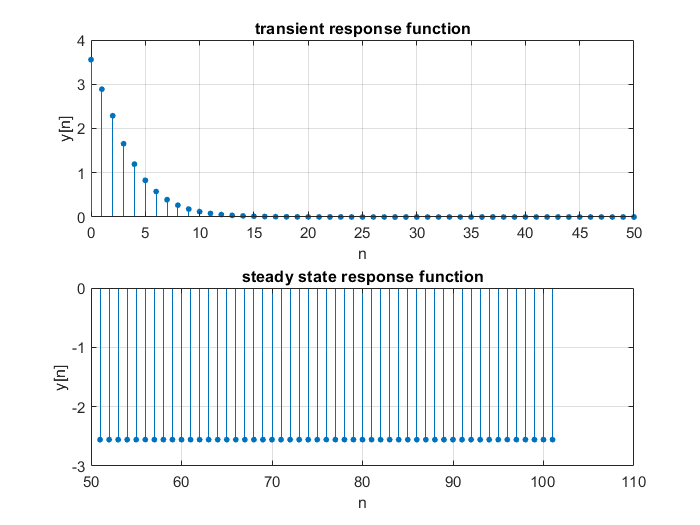

subplot(2,1,1); 
stem(0:50,s(1:51) - s(end),'filled','MarkerSize',3); grid;
xlabel('n'); title('transient response function'); 
ylabel('y[n]');
subplot(2,1,2); 
stem(51:101,s(51:end),'filled','MarkerSize',3); grid;
xlabel('n'); title('steady state response function'); 
ylabel('y[n]');

function X = dtft(x)
% we divide [-pi, pi] into N+1 points.
    k = 1 : length(x);
    N = 500;
    w = linspace(-pi,pi,N + 1);
    X = x * (exp(-1i*k'*w));
    % if we want to plot dtft signal
    plot_dtft(X,w)
end
function H = diff_resp(a,b)
    kx = 1 : length(b);
    ky = 1 : length(a);
    N = 500;
    w = linspace(-pi,pi,N + 1);
    H = (b * exp(-1i*kx'*w)) ./ (1 + a *exp(-1i*ky'*w));
    plot_dtft(H,w)
end
function plot_dtft(X,w)
magX = abs(X); angX = angle(X);
subplot(2,1,1); plot(w/pi,magX); grid
xlabel('\omega / \pi'); title('Magnitude Part'); ylabel('Magnitude')
subplot(2,1,2); plot(w/pi,angX); grid
xlabel('\omega / \pi'); title('Angle Part'); ylabel('Radians')
end
function [X,w] = dtft_no_plot(x)
% we divide [-pi, pi] into N+1 points.
    k = 1 : length(x);
    N = 500;
    w = linspace(-pi,pi,N + 1);
    X = x * (exp(-1i*k'*w));
end


function y = ideal_interpolation(x,Ts,t)
    n = 0: length(x) - 1;
    Fs = 1/Ts;
    nTs = n *Ts;
    y = x*sinc(Fs*(ones(length(n),1)*t-nTs'*ones(1,length(t))));
end

function [y] = linear_interpolation (x,t,L)
    n = 0: length(x) - 1;
    xl = expander(x,L);
    n = 0:length(t) - 1;
    x_lin = [zeros(1,L-1) xl zeros(1,L-1)];
    n_lin = [-L+1:0 n length(n):length(n)+L-1];
    y = zeros(1,length(n));
    for i = 0:length(t) - 1
        y(i+1) = sum(x_lin((i+1):(i+2*L-1)).*(1-abs(i-n_lin((i+1):(i+2*L-1)))/L));
    end
end
function y = zero_order_interpolation(x,t,L)
    n = 0: length(x) - 1;
    xl = expander(x,L);
    y = zeros(1,length(n));
    for i = 0:length(t) - 1
        if xl(i + 1) ~= 0
           y(i+1) = xl(i + 1);
        else
            y(i+1) = y(i);
        end
    end
end

function y = spline_interpolation(x,t,Ts)
    n = 0: length(x) - 1;
    nTs = n*Ts;
    y = spline(nTs,x,t);
end


function y = compressor(x,M)
    y = x(M:M:length(x));
end

function y = expander(x,L)
    for n=1:L*length(x)
        if mod(n,L) == 0
            y(n) = x(n/L);
        else
            y(n) = 0;
        end
    end
    y = y(L:end);
end